%% Datos de calibración para GP2Y0A41 (A6) - Sensor Derecho
adc_A6 = [4057.8, 3040.2, 2258.5, 1935.8, 1712.5, 1538.7, 1327.8, 1203.7, 1092.0, 1054.8, 1005.1, 918.3, 881.0];
distancias_A6 = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50, 55, 60, 65];

%% Datos de calibración para GP2Y0A21 (A7) - Sensor Izquierdo
adc_A7 = [3970.909	2916.136	1985.455	1600.773	1464.273	1240.909	1079.591	930.682	881.045	806.591	781.773	707.318	620.455	620.455];
distancias_A7 = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50, 55, 60, 65, 70];

%% Ajuste para GP2Y0A41 (A6)
modelo_potencia = @(params, x) params(1) * x.^params(2);
params_iniciales = [1, -1];

% Ajuste de curva no lineal para A6
params_A6 = lsqcurvefit(modelo_potencia, params_iniciales, adc_A6, distancias_A6);


Solver stopped prematurely.

lsqcurvefit stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 2.000000e+02.



a_A6 = params_A6(1);
b_A6 = params_A6(2);

% Gráfico para A6
figure;
subplot(2,1,1);
plot(adc_A6, distancias_A6, 'ro', 'MarkerSize', 8, 'LineWidth', 2);
hold on;
adc_teorico_A6 = linspace(min(adc_A6), max(adc_A6), 100);
plot(adc_teorico_A6, modelo_potencia(params_A6, adc_teorico_A6), 'b-', 'LineWidth', 2);
title('Calibración GP2Y0A41 (A6) - Distancia vs ADC');
xlabel('Valor ADC (12 bits)');
ylabel('Distancia (cm)');
legend('Datos reales', sprintf('Modelo: %.2f * ADC^{%.4f}', a_A6, b_A6), 'Location', 'northeast');
grid on;

%% Ajuste para GP2Y0A21 (A7)
% Ajuste de curva no lineal para A7
params_A7 = lsqcurvefit(modelo_potencia, params_iniciales, adc_A7, distancias_A7);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


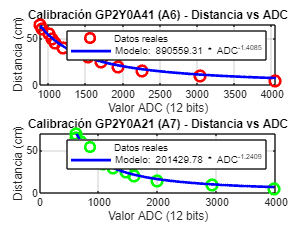

a_A7 = params_A7(1);
b_A7 = params_A7(2);

% Gráfico para A7
subplot(2,1,2);
plot(adc_A7, distancias_A7, 'go', 'MarkerSize', 8, 'LineWidth', 2);
hold on;
adc_teorico_A7 = linspace(min(adc_A7), max(adc_A7), 100);
plot(adc_teorico_A7, modelo_potencia(params_A7, adc_teorico_A7), 'b-', 'LineWidth', 2);
title('Calibración GP2Y0A21 (A7) - Distancia vs ADC');
xlabel('Valor ADC (12 bits)');
ylabel('Distancia (cm)');
legend('Datos reales', sprintf('Modelo: %.2f * ADC^{%.4f}', a_A7, b_A7), 'Location', 'northeast');
grid on;


%% Mostrar resultados
fprintf('=== Resultados de calibración ===\n');

=== Resultados de calibración ===


fprintf('Sensor GP2Y0A41 (A6): distancia = %.4f * ADC^(%.4f)\n', a_A6, b_A6);

Sensor GP2Y0A41 (A6): distancia = 890559.3060 * ADC^(-1.4085)


fprintf('Sensor GP2Y0A21 (A7): distancia = %.4f * ADC^(%.4f)\n', a_A7, b_A7);

Sensor GP2Y0A21 (A7): distancia = 201429.7845 * ADC^(-1.2409)



%% Función para implementar en Arduino
fprintf('\n=== Código para Arduino ===\n');


=== Código para Arduino ===


fprintf('// Parámetros calibración\n');

// Parámetros calibración


fprintf('const float a_A6 = %.4f; // Sensor derecho (A6)\n', a_A6);

const float a_A6 = 890559.3060; // Sensor derecho (A6)


fprintf('const float b_A6 = %.4f;\n', b_A6);

const float b_A6 = -1.4085;


fprintf('const float a_A7 = %.4f; // Sensor izquierdo (A7)\n', a_A7);

const float a_A7 = 201429.7845; // Sensor izquierdo (A7)


fprintf('const float b_A7 = %.4f;\n\n', b_A7);

const float b_A7 = -1.2409;




fprintf('float readSharpCM(int pin, int adc_value) {\n');

float readSharpCM(int pin, int adc_value) {


fprintf('  if (pin == A6) {\n');

  if (pin == A6) {


fprintf('    return a_A6 * pow(adc_value, b_A6);\n');

    return a_A6 * pow(adc_value, b_A6);


fprintf('  } else { // A7\n');

  } else { // A7


fprintf('    return a_A7 * pow(adc_value, b_A7);\n');

    return a_A7 * pow(adc_value, b_A7);


fprintf('  }\n');

  }


fprintf('}\n');

}
